# Results

## Config

% add directory to search path
addpath('./libs');

path = './data/ep20c11/noisy/results/test';
viz = Viz(path);

## Structure of Network

The network structure of the model which is shown as a *directed acyclic graph* (**DAG**).

Different parts of the model:

- Orange disk with label ***s*** indicates stimulus/input

- Orange disk with label ***r*** indicates expected response/output (this data is used just for training step)

- Green disks indicate the parameters (or unknows parameters which must be fine-tuned during the learning process)

- Red disk indicates the actual response/output

- Purple disk indicates the cost (the distance between the expected output and the actual output)

- Blue squares indicate layers (computational blocks). The ***+*** sign in their name show the sequential chain of them

- .

- Blue disks indicate the output of the layers

Abbreviations:

- s : Stimulus

- r : Response

- w: Weight/Kernel

- B : Bipolar

- A : Amacrine

- G : Ganglion

- c : Cost

- conv : Convolution

- relu : Rectified Linear Unit

- neg : Negation

- sum: Sum

- quadcost: Quadratic Cost

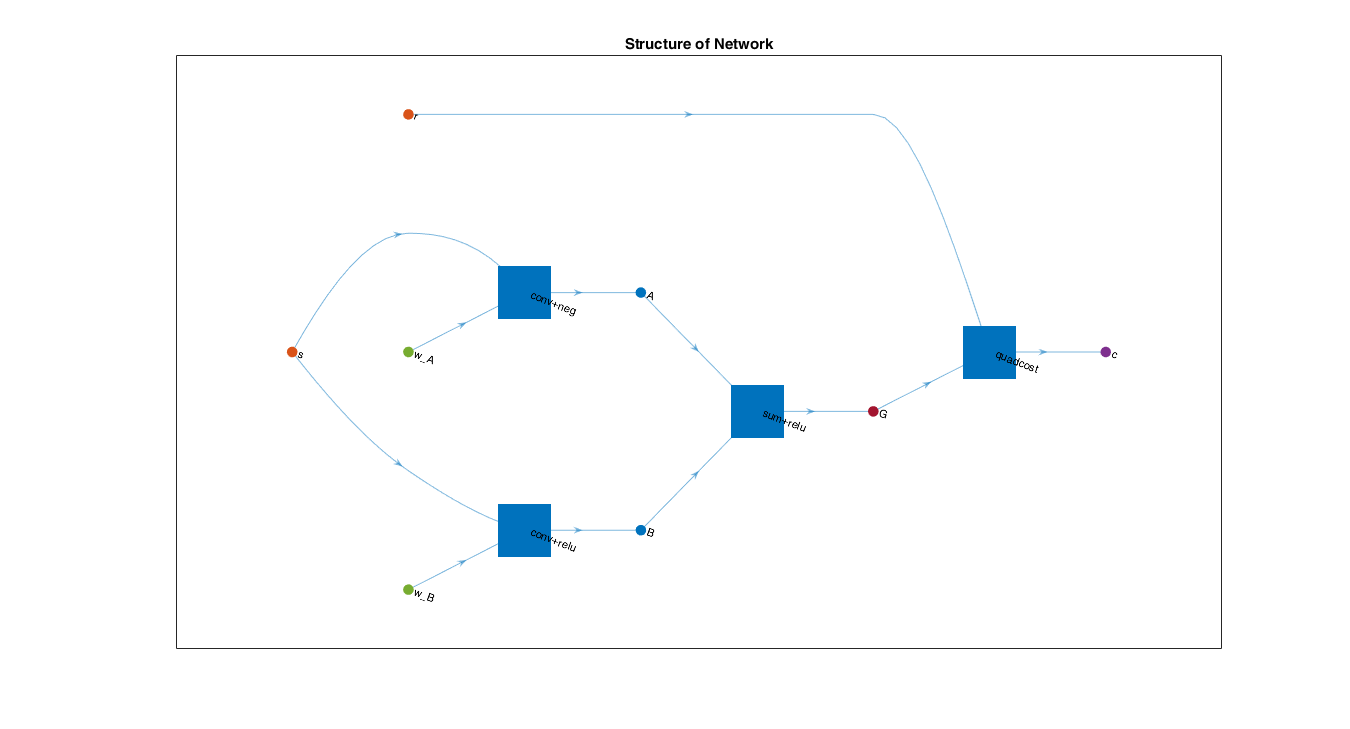

viz.plotNet();

## Data

These plots show the pairs of stimulae (blue) compared to their respective expected responses (orange). 

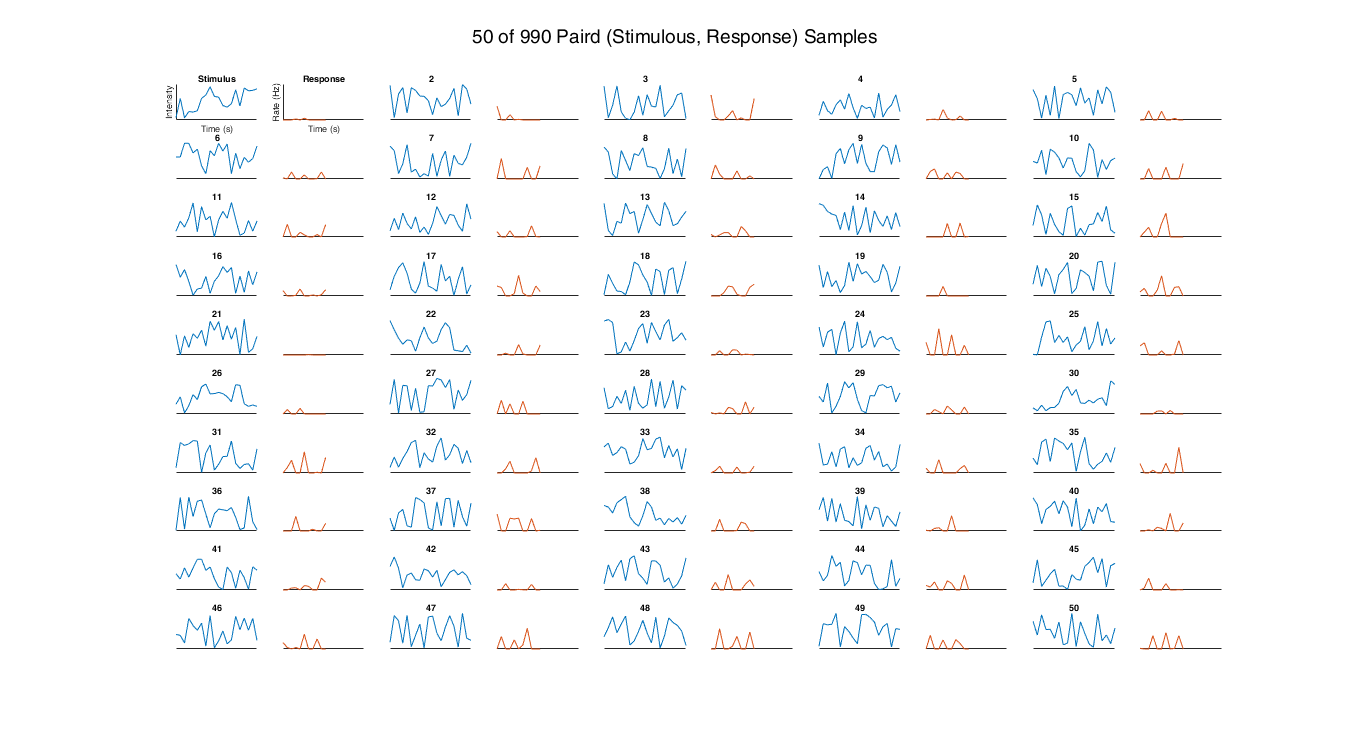

viz.plotData(1:50);

These plots show the pair of stimulus (blue) compared to its respective expected response (orange).

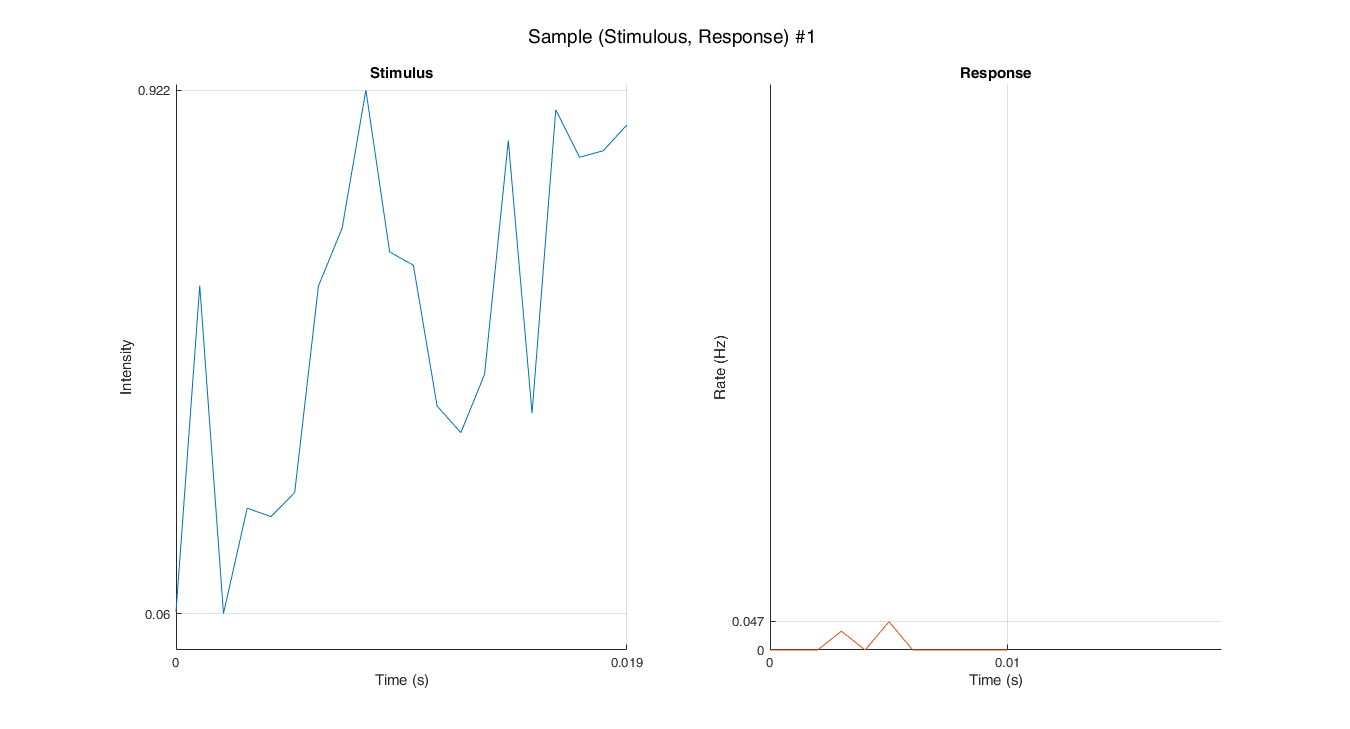

viz.plotSample(1);

These box plots show the instensity distribution in out stimulus and the frequency distribution of our response. The stimulus is uniformly distributed across the range 0 to 1 in intensity, while the response seems to follow a gaussian distribution (not sure) with mean 0.

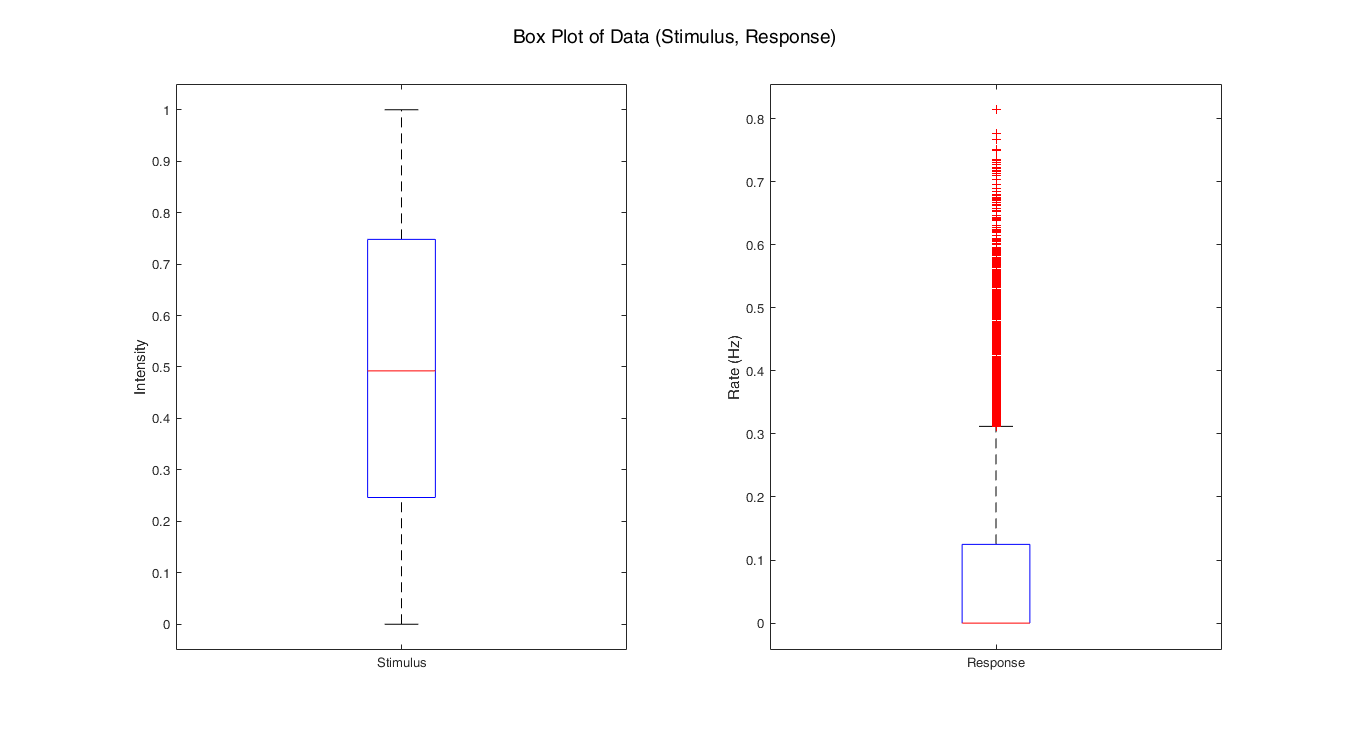

viz.boxplotData();

The color plot shows the distribution of how the data is divided into training, validation and testing. 70% of the total data is training data displayed in blue. 15% is reserved for validation, used to tune hyperparameters, shown in green. 15% is taken to be the test data, which is used to evaluate the network for the final test, shown in red.

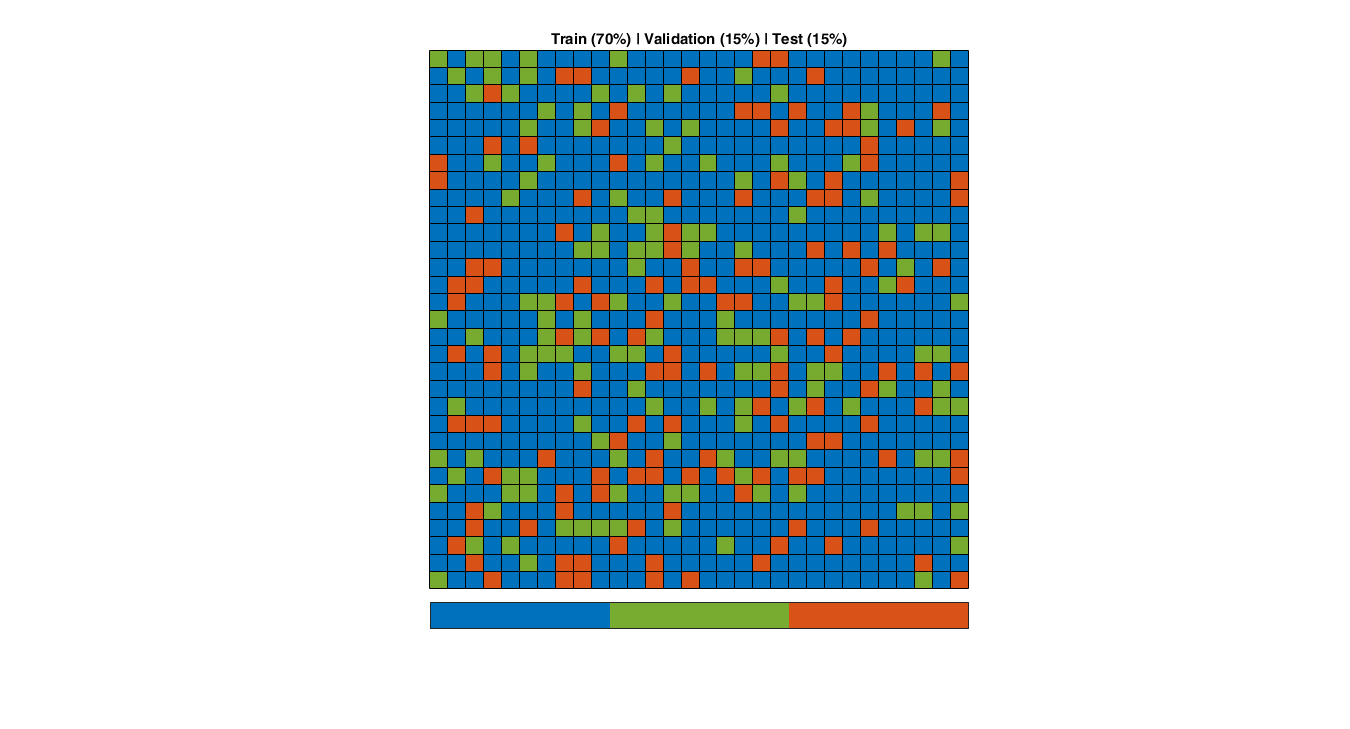

viz.boardplotData();

## Costs

This plot shows the error measured on the validation dataset after traning for a certain amount of epochs on the traning set. We see a steady decline in error as the amount of epochs increases. Minimum validation error was obtained at epoch 399 in both plots. The error trend at the end seemed to be decreasing still, so it might be benefitial for us to run the learning for more epochs.

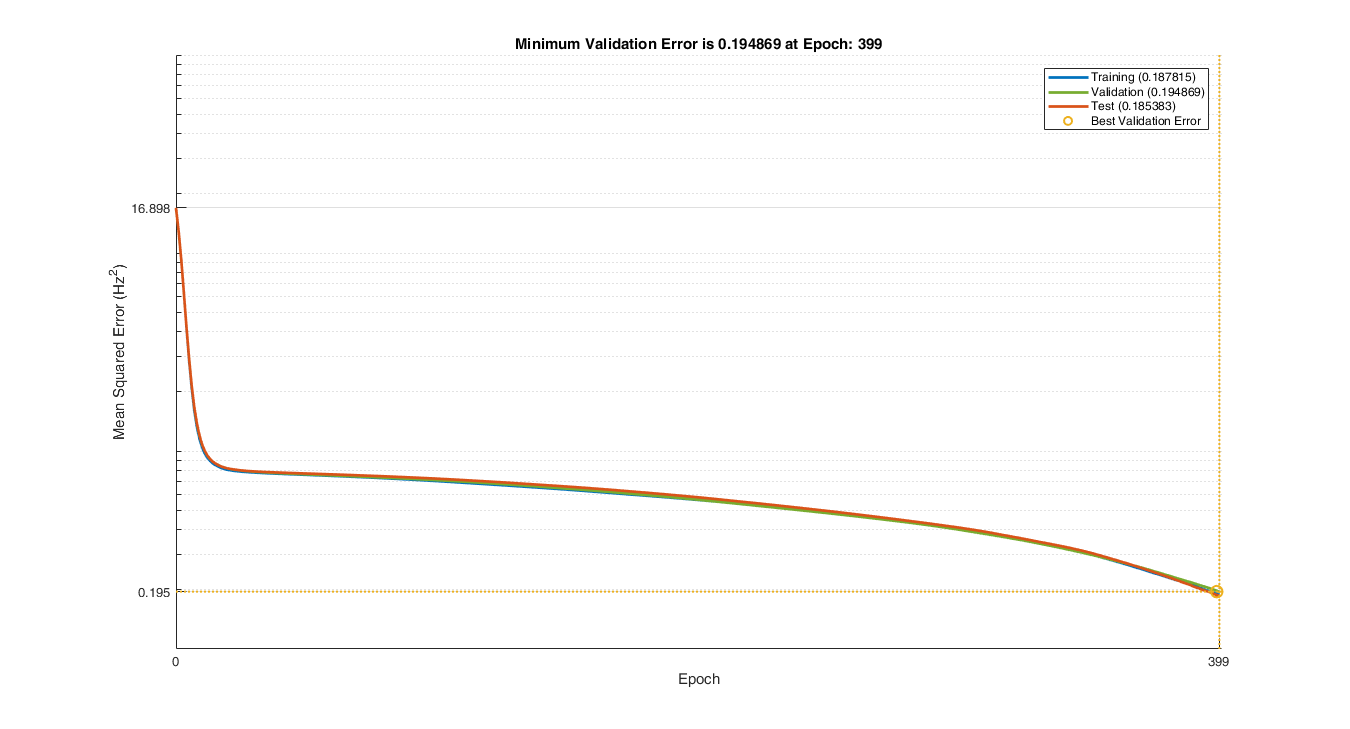

viz.plotCosts();

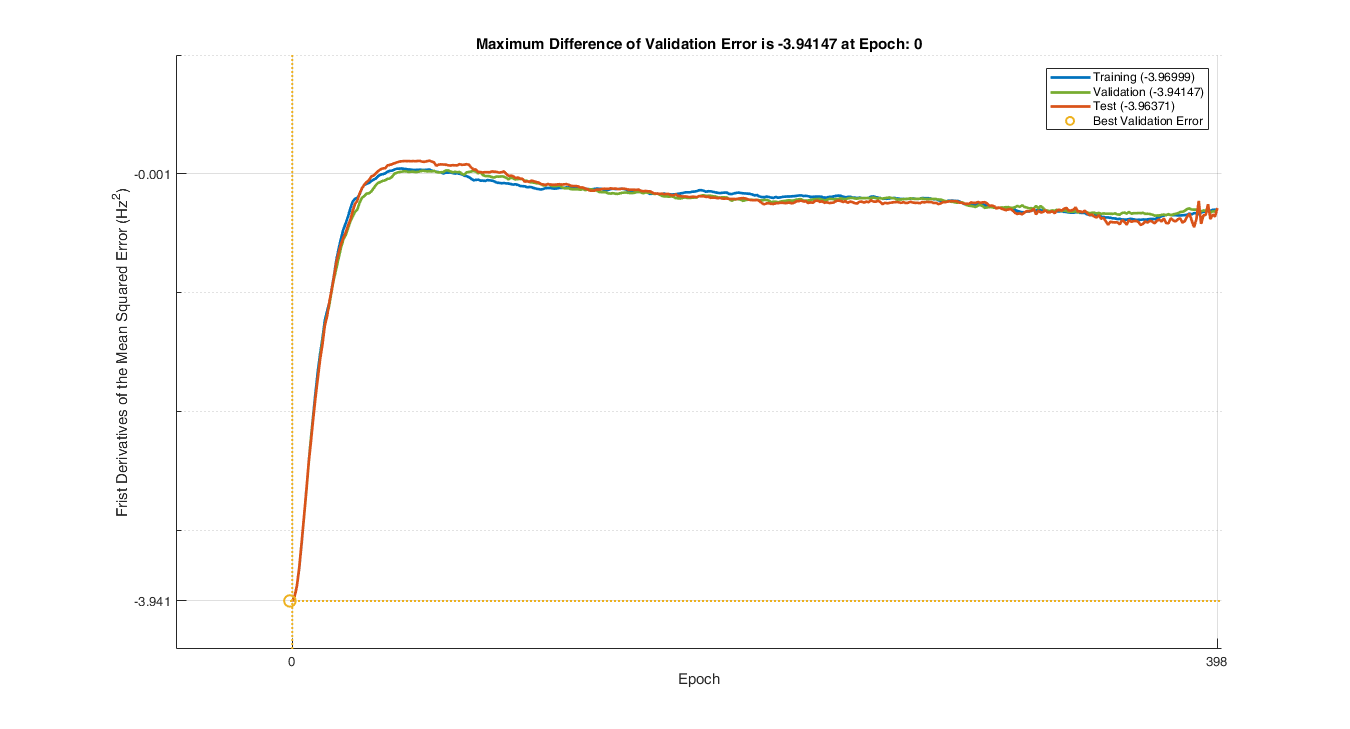

viz.plotCosts('diff');

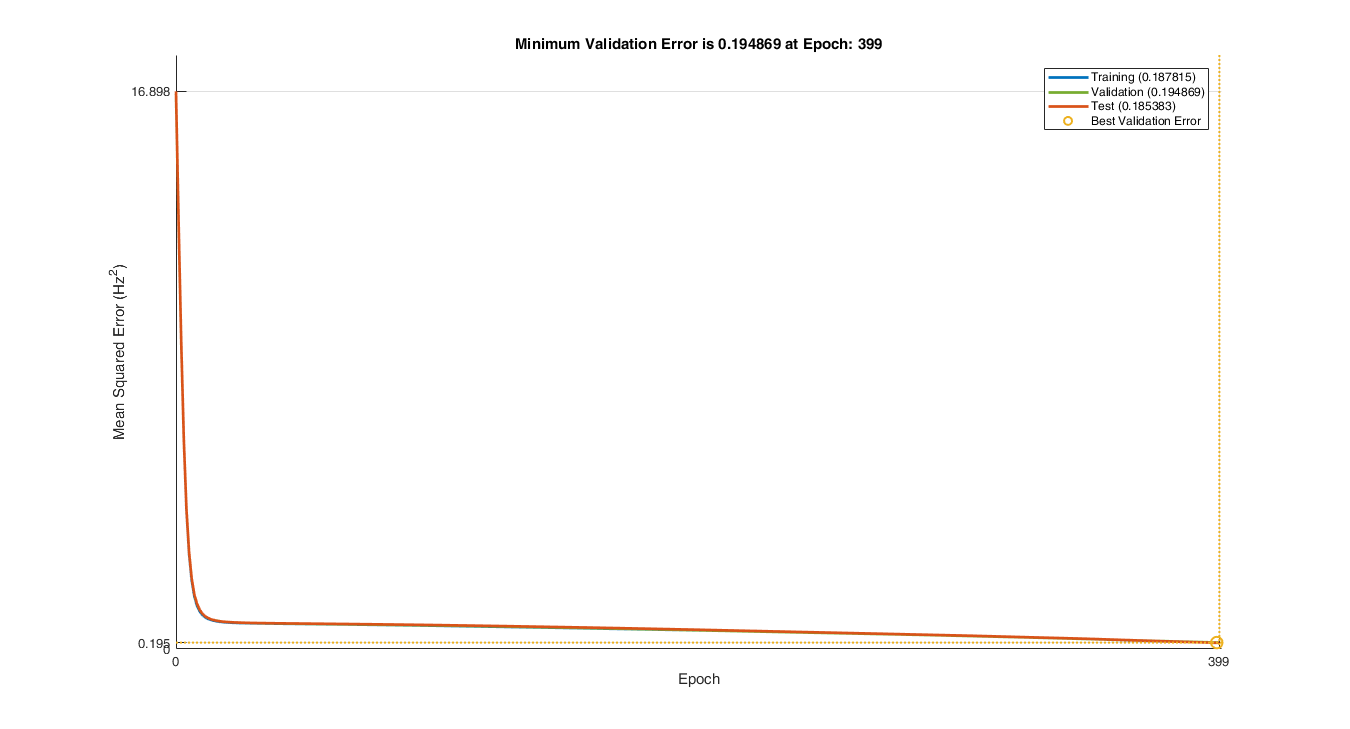

viz.plotCosts([], 'linear');

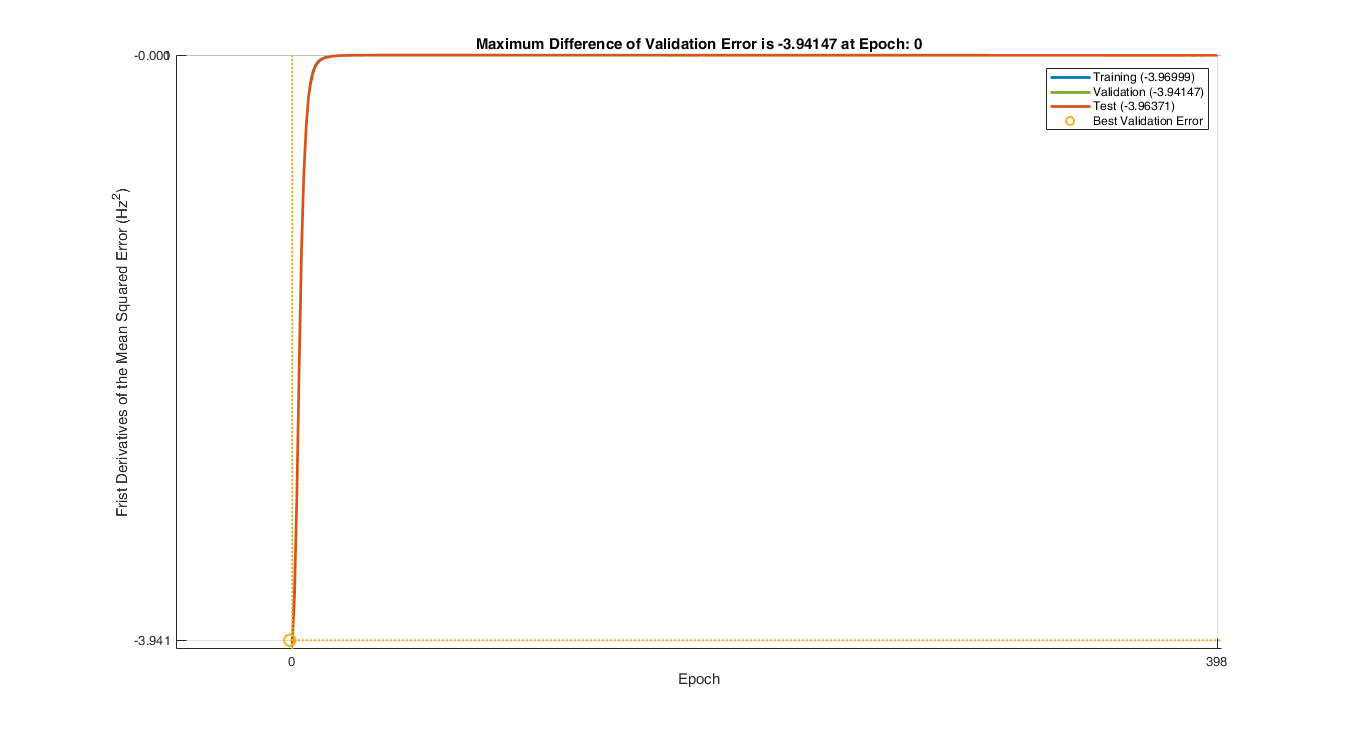

viz.plotCosts('diff', 'linear');

## Filters

w_B and w_A are the weight vectors for the conv+neg layers and the con+relu layers respectively.  These are the parameters that change as the learning process occurs.

viz.paramNames

ans = 1×2 cell array
    'w_B'    'w_A'


These plots show the ground truth or expected weight vector values for w_B and w_A respectively, along with their initial values when learning and their best results after learning. w_B seemed to have seen significant learning progress, while w_A seems to remain stagnant as it only sees a vertical shift in its values.

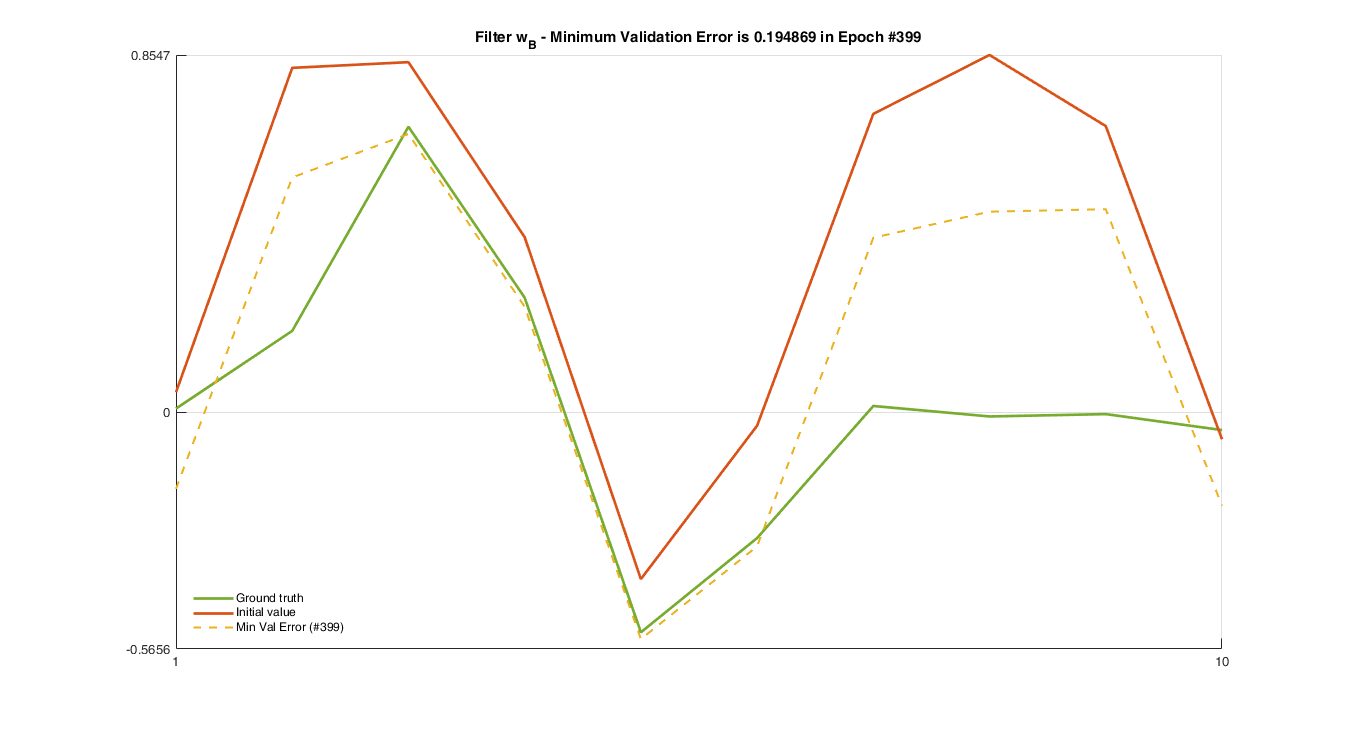

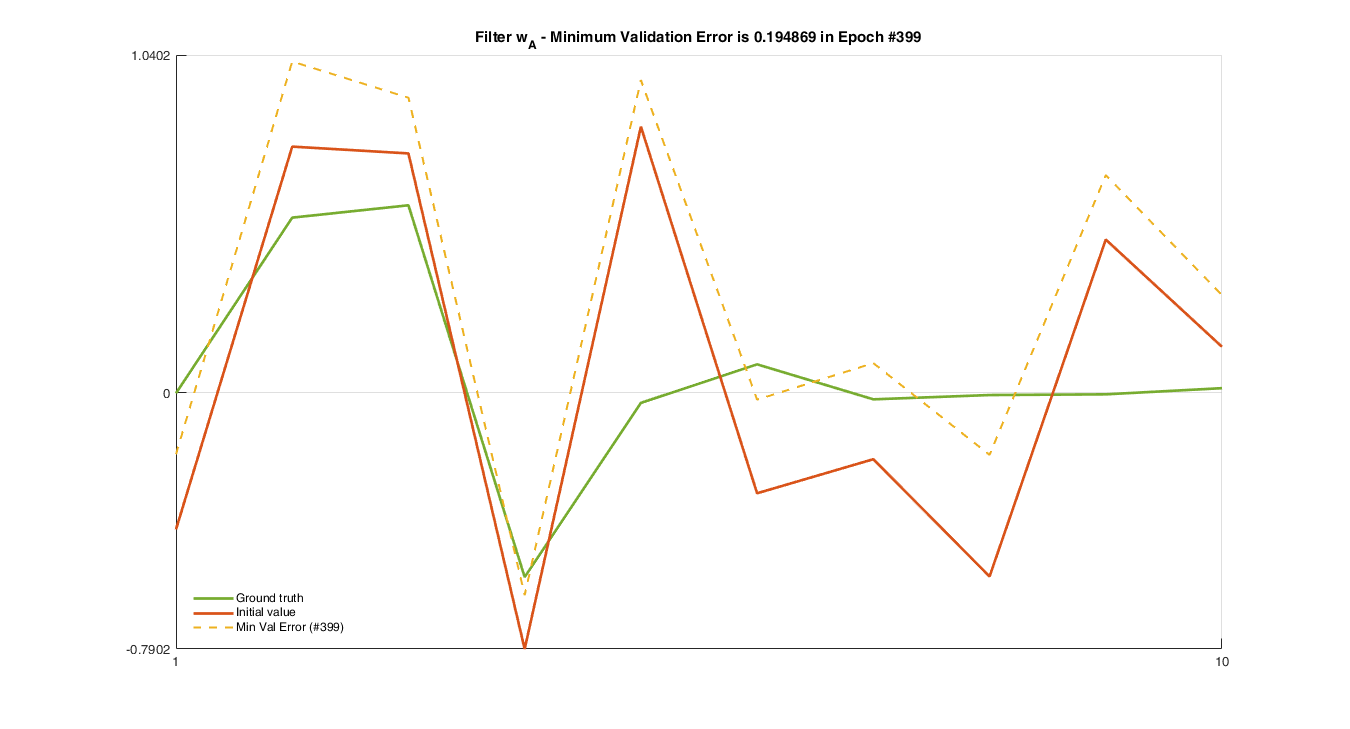

viz.plotFilter();

Video sequence of how w_B and w_A change throughout the learning process compared witht ground truth and initial values.

Sequence of small plots of what w_B and w_A look like over the 399 epochs learning runs for.

Video path: '.\data\ep20c11\noisy\results\test\vidoes\w_B.mp4'

Video path: '.\data\ep20c11\noisy\results\test\vidoes\w_A.mp4'

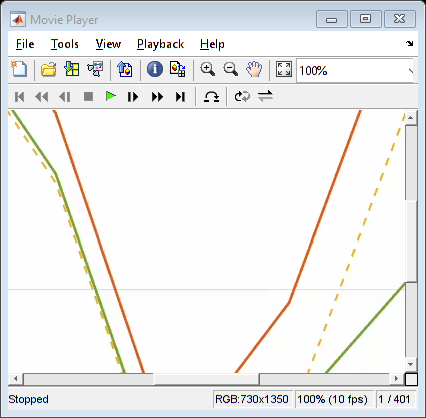

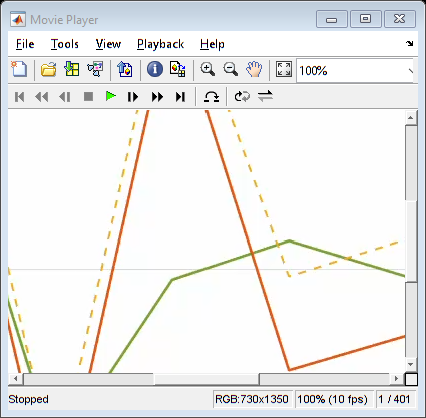

viz.playFilterVideo();

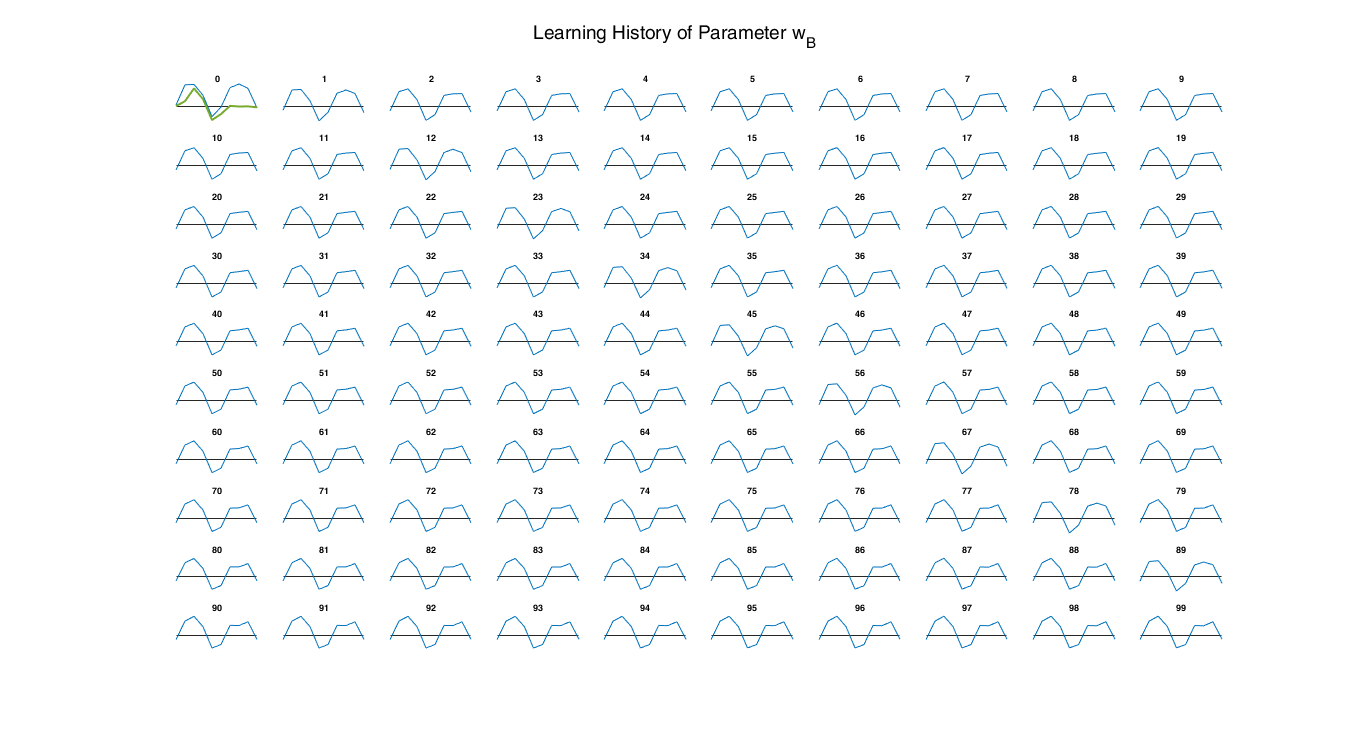

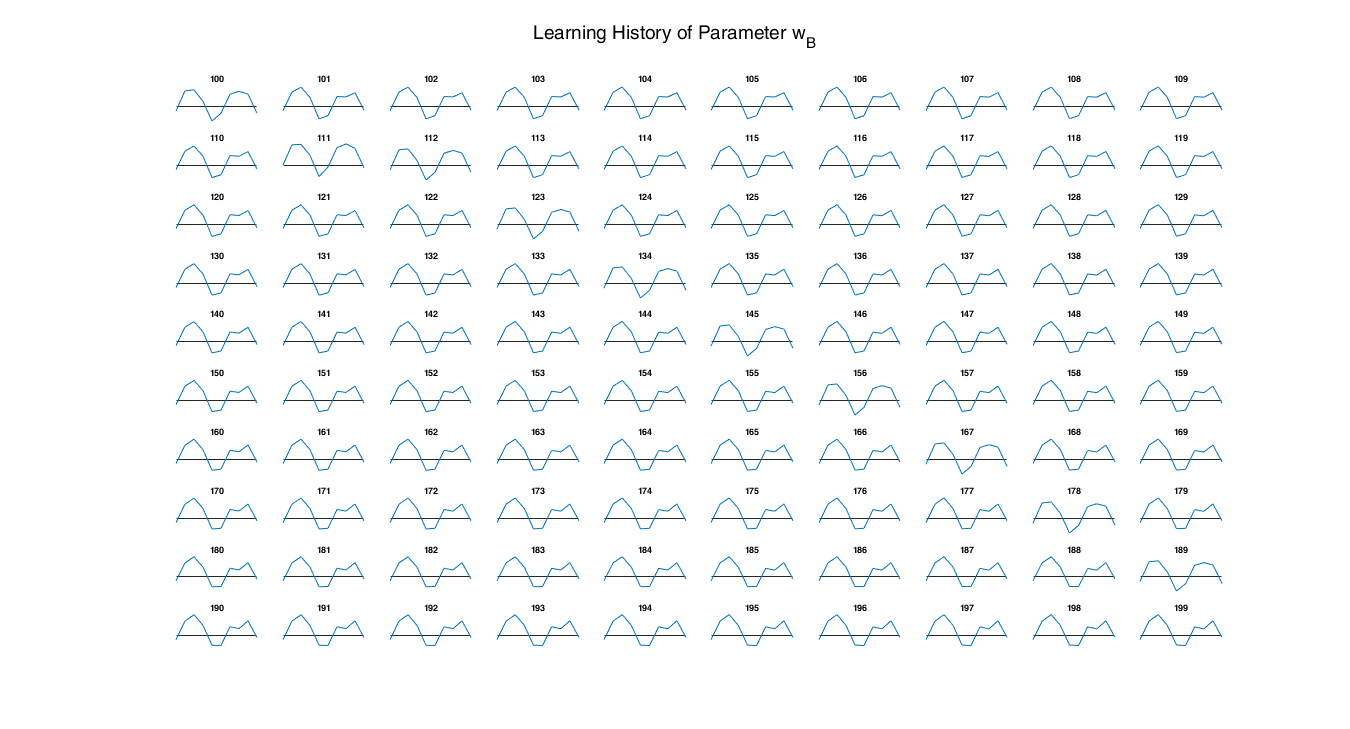

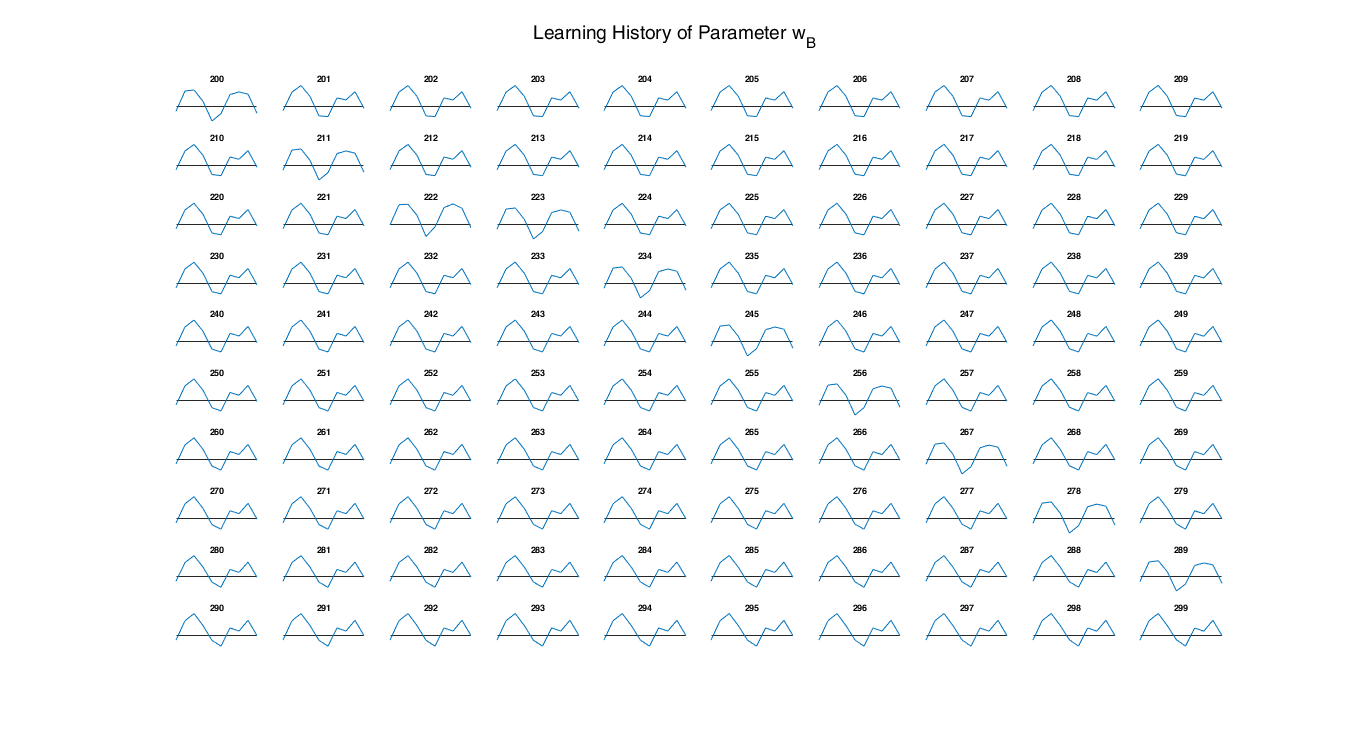

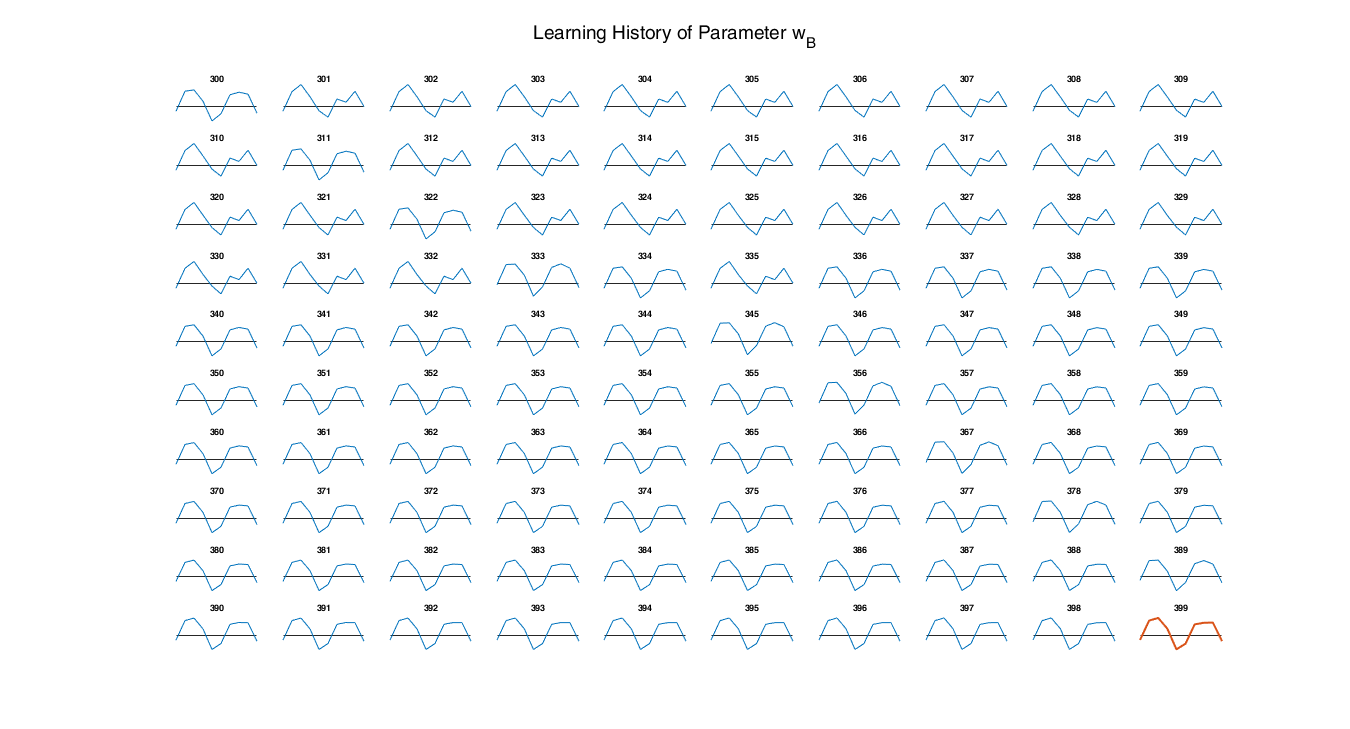

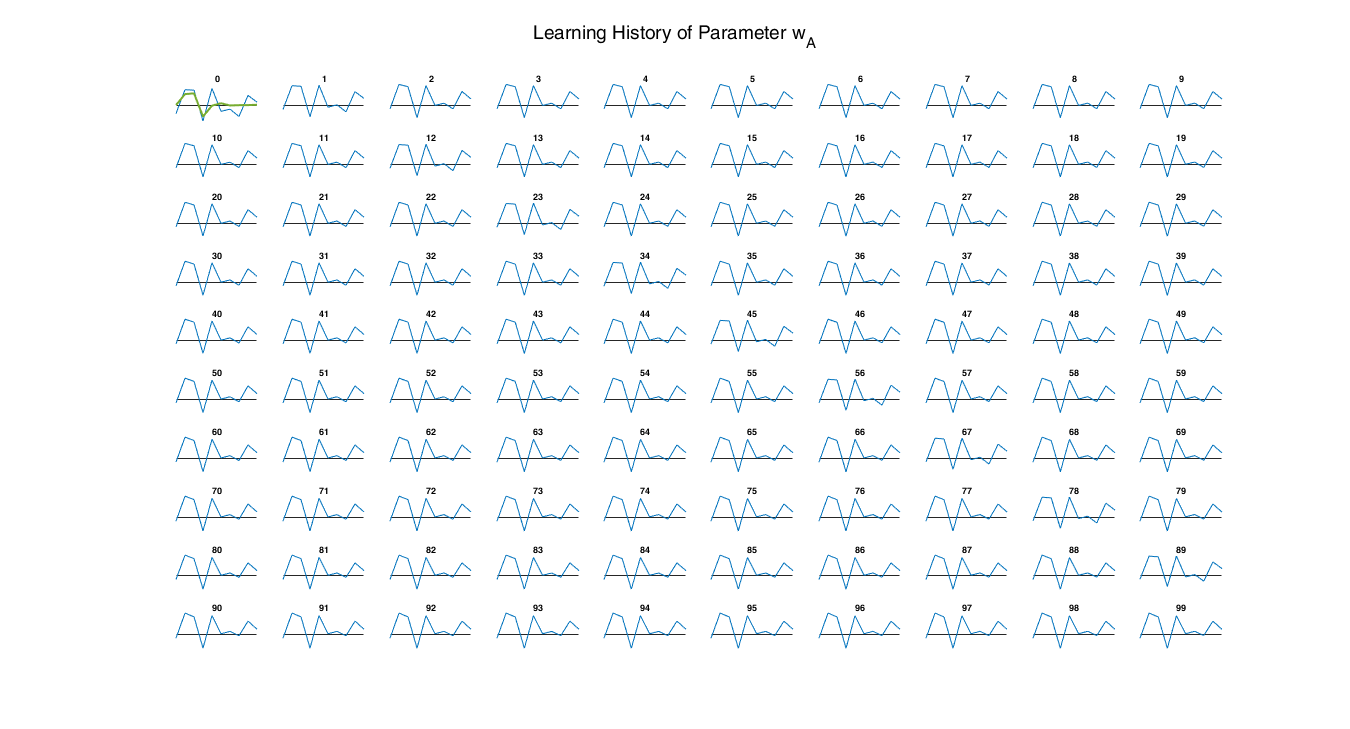

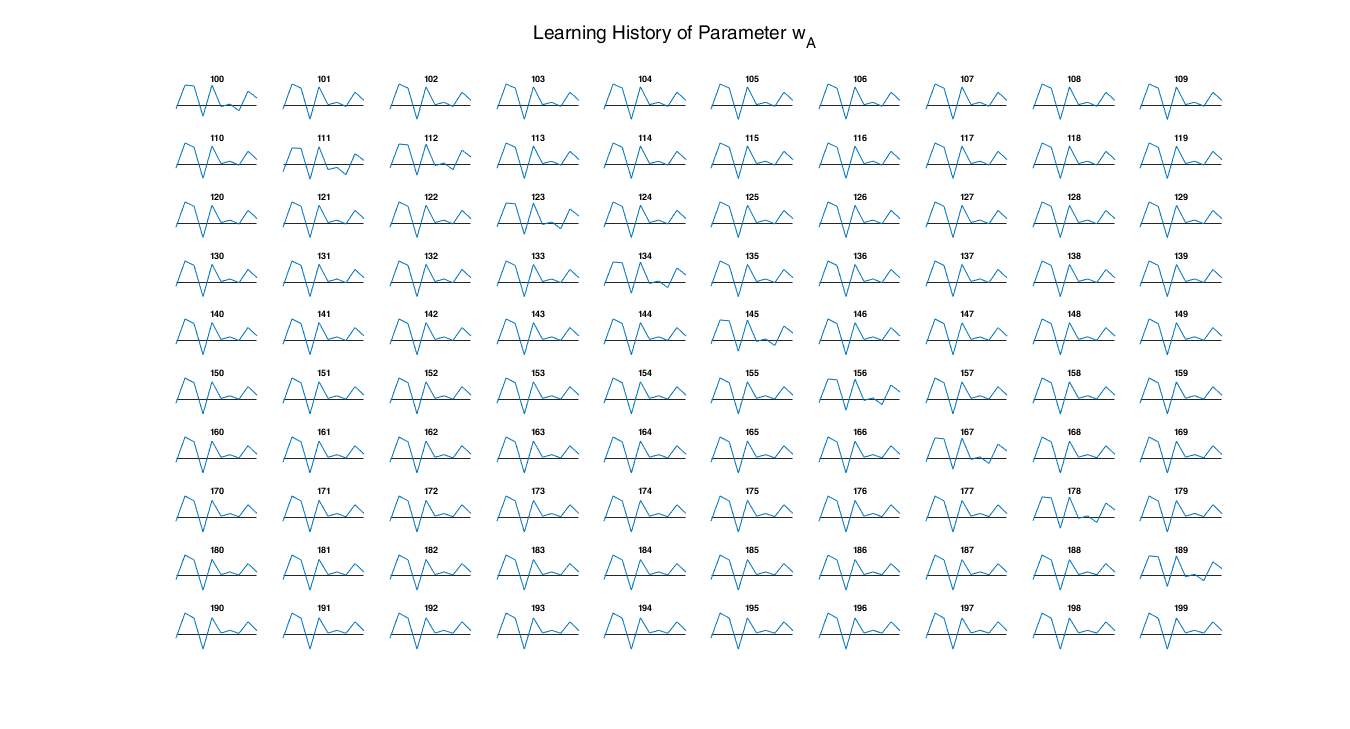

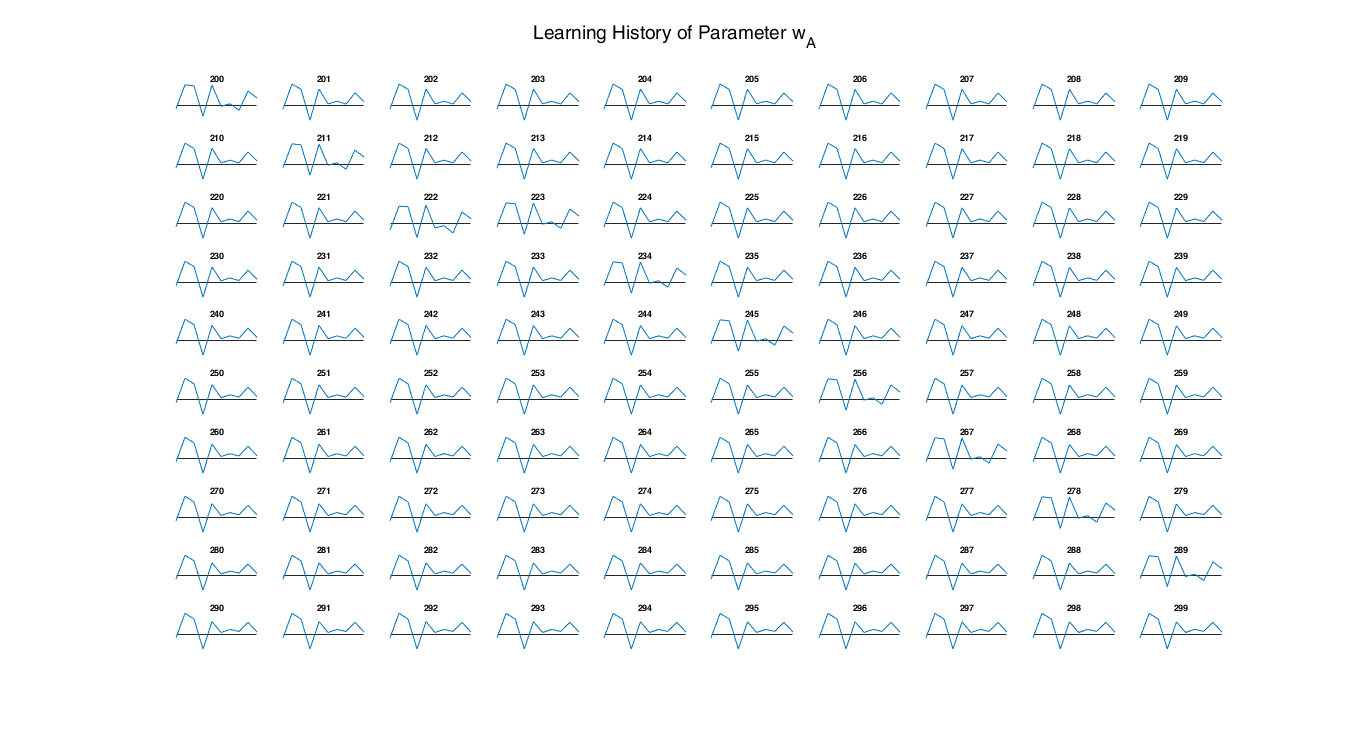

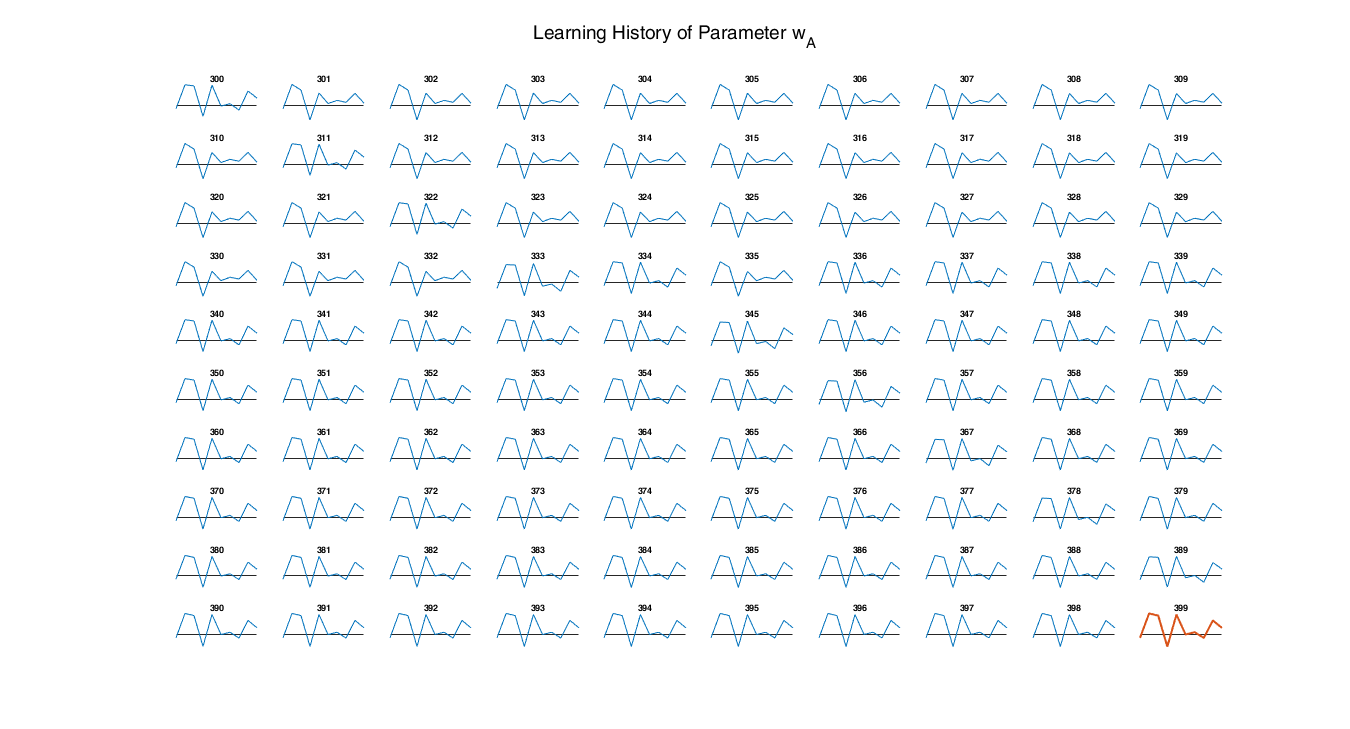

viz.plotFilterHistory();